windowSizes = [50,100,200,400,800,1000]

windowSizes =           50         100         200         400         800        1000


results = struct();
bestModeltypes = cell(length(windowSizes),1);

opt = struct('UseParallel', true);

%hyperOpts = struct('Optimizer', 'bayesopt', 'ShowPlots', true, 'CV', 10, 'MaxObjectiveEvaluations', 150, 'UseParallel', true); 

optimizedModels = cell(length(windowSizes), 1);
bestHyperparameters = cell(length(windowSizes), 1);

accuracies = zeros(length(windowSizes), 1);  % To store the accuracy for each window size
t = templateTree('Reproducible',true);

Copying objective function to workers...
Done copying objective function to workers.
|===============================================================================================================|
| Iter | Active  | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | NumLearningC-|    LearnRate |
|      | workers | result |             | runtime     | (observed)  | (estim.)    | ycles        |              |
|===============================================================================================================|
|    1 |       6 | Best   |     0.27834 |      11.557 |     0.27834 |     0.27834 |           13 |    0.0021595 |
|    2 |       6 | Best   |     0.26341 |      24.558 |     0.26341 |     0.26418 |           30 |      0.63637 |
|    3 |       6 | Accept |     0.26783 |      9.8192 |     0.26341 |     0.26408 |           13 |      0.78316 |
|    4 |       6 | Accept |     0.26654 |      20.818 |     0.26341 |     0.26555 |           29 |      0.48025 |
|  

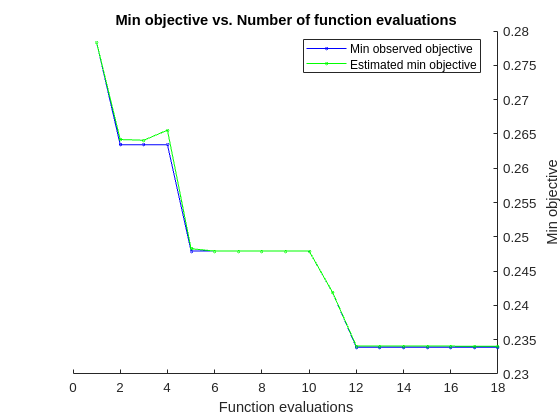

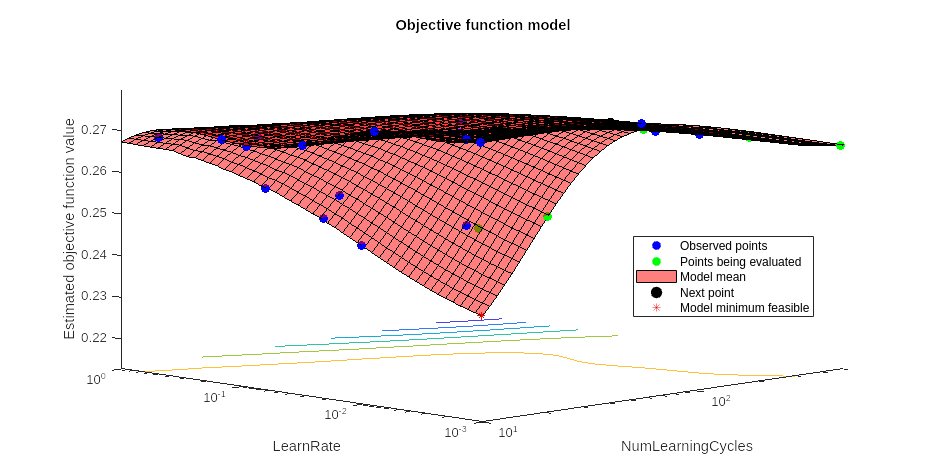

ans =   Map with properties:

        Count: 6
      KeyType: char
    ValueType: any


ans =   Map with properties:

        Count: 6
      KeyType: char
    ValueType: any


for i=1:6
    binn_Aluminum = getAllBinned(referance_table.AluminumSDF,windowSizes(i));
    binn_Attenuated = getAllBinned(referance_table.AttenuatedSDF,windowSizes(i));
    binn_NoObject = getAllBinned(referance_table.NoObjectSDF,windowSizes(i));
    binn_NoWhisking = getAllBinned(referance_table.NoWhiskingSDF,windowSizes(i));
    all_binned = [binn_Aluminum,binn_Attenuated,binn_NoObject,binn_NoWhisking]';
    allBinned = zscore(all_binned);
    labels = [repmat({'Aluminum'},length(binn_Aluminum),1);repmat({'Attenuated'},length(binn_Attenuated),1);repmat({'No object'},length(binn_NoObject),1);repmat({'No whisking'},length(binn_NoWhisking),1)];
    subsetSize = 0.15;
    cv_bin = cvpartition(labels, 'HoldOut', 0.05);
    all_binned_train = all_binned(cv_bin.training,:);
    all_labels_train = labels(cv_bin.training);
    idx = randperm(size(all_binned_train, 1), floor(subsetSize * size(all_binned_train, 1)));
    X_subset = all_binned_train(idx, :);
    Y_subset = all_labels_train(idx);
    cv_train = cvpartition(Y_subset,'KFold',10);
    test_labels = labels(cv_bin.test);
    binned_test = all_binned(cv_bin.training);
    hyperOpts = struct('Optimizer', 'bayesopt', 'ShowPlots', true, 'CV', cv_train, 'MaxObjectiveEvaluations', 150, 'UseParallel', true); 
    Mdl_optimized = fitcensemble(X_subset, Y_subset, 'Method', 'AdaBoostM2', 'Learners', t, 'OptimizeHyperparameters', {'NumLearningCycles', 'LearnRate'}, 'HyperparameterOptimizationOptions', hyperOpts);
    optimizedModels{i} = Mdl_optimized;
    bestHyperparameters{i} = Mdl_optimized.HyperparameterOptimizationResults.XAtMinEstimatedObjective;
    predicted_labels = Mdl_optimized.predict(binned_test);
    accuracies(i) = sum(predicted_labels == test_labels);
end

Mdl50 = Mdl;

function allBinned = getAllBinned(sdfCondition,winSize)
    for un = 1:length(sdfCondition)
        allBinned(un,:) = binCond(winSize,sdfCondition{un});
    end
end
function binnedV = binCond(winSize,sdfV)
    modAl = mod(length(sdfV),winSize);
    sdfVS = sdfV(1:end-modAl);
    binnedV = mean(reshape(sdfVS,winSize,[]));
end
